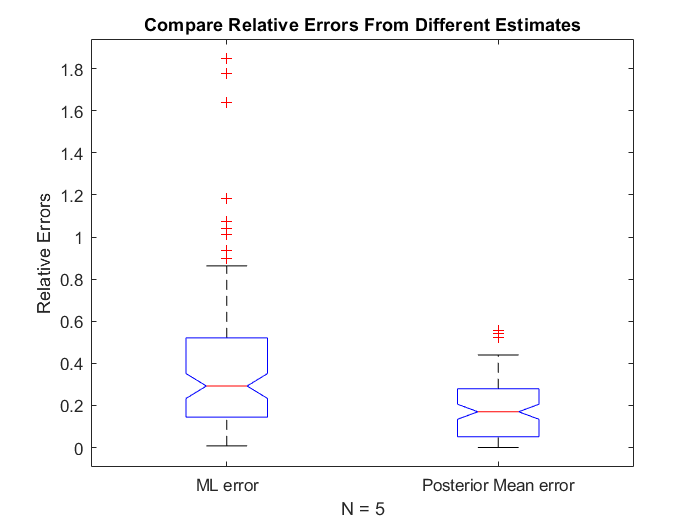

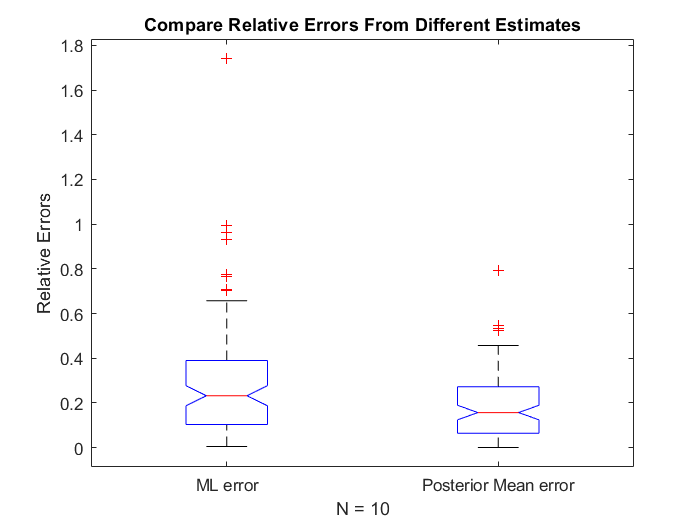

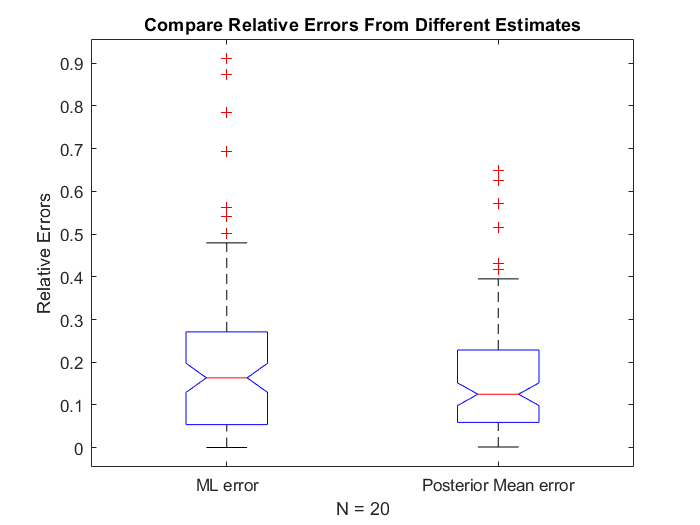

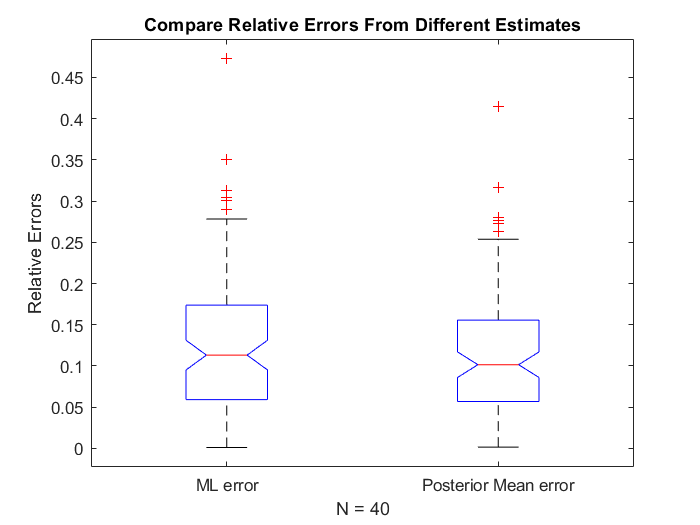

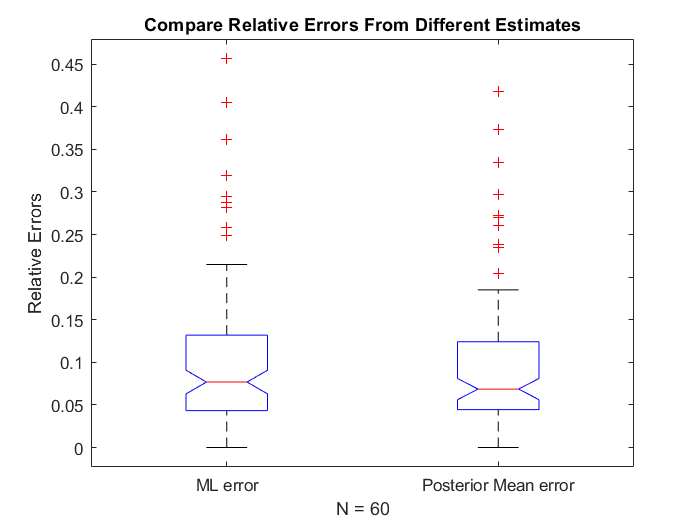

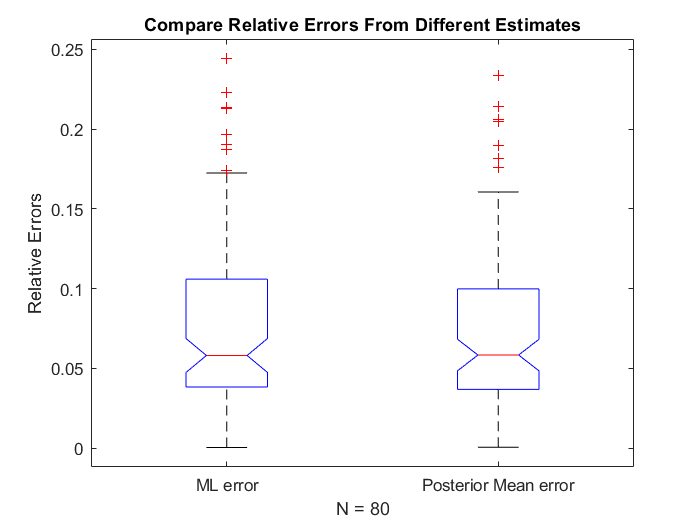

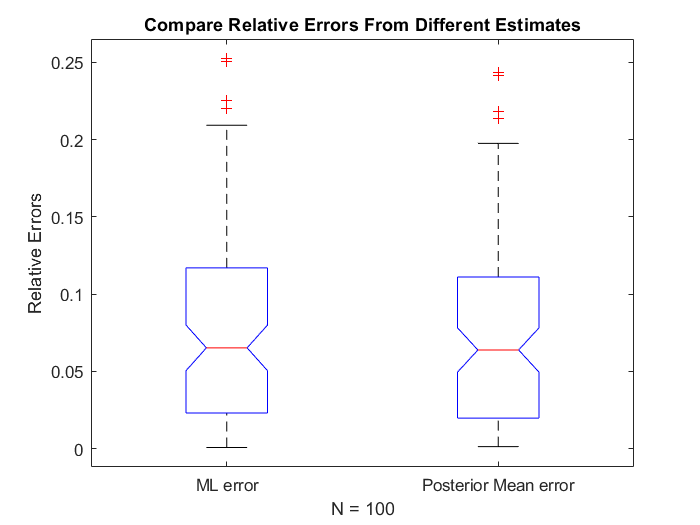

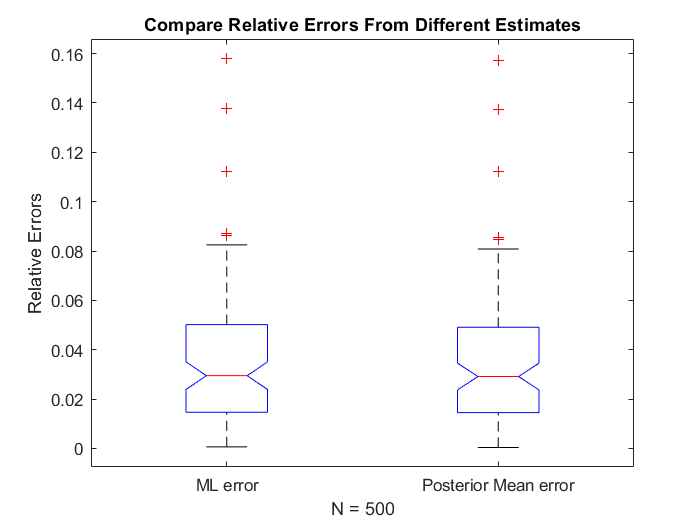

rng("default")

N = [5, 10, 20, 40, 60, 80, 100, 500, 1000 10000];
m = 100;
errors_ML = zeros(m,10);
errors_posterior = zeros(m,10);
for j = 1:10
    n = N(j);
    lambda = 5;
    error_ML = zeros(m,1);
    error_posterior = zeros(m,1);
    for i = 1:m
        uniform_data = rand(1,n);
        transformed_data = -1*log(uniform_data)/lambda;

        % Finding the ML estimate which is equal to reciprocal of sample
        % mean for exponential distribution
        sample_mean = sum(transformed_data)/n;
        lambda_ML = 1/sample_mean;
        
        % The Prior is a gamma function with parameters:s
        alpha = 5.5;
        beta = 1;

        % Finding the Posterior Mean
        alpha_posterior = alpha + n;
        beta_posterior = beta + sum(transformed_data);

        lambda_posterior_mean = alpha_posterior/beta_posterior;

        error_ML(i,1) = abs(lambda_ML - lambda)/lambda;
        error_posterior(i,1) = abs(lambda_posterior_mean-lambda)/lambda;
    end
    figure
    boxplot([error_ML,error_posterior],'Notch','on','Labels',{'ML error','Posterior Mean error'},'Whisker',1)
    title(sprintf('Compare Relative Errors From Different Estimates'))
    xlabel(sprintf('N = %d',n))
    ylabel('Relative Errors')
    errors_ML(:,j) = error_ML;
    errors_posterior(:,j) = error_posterior;
end

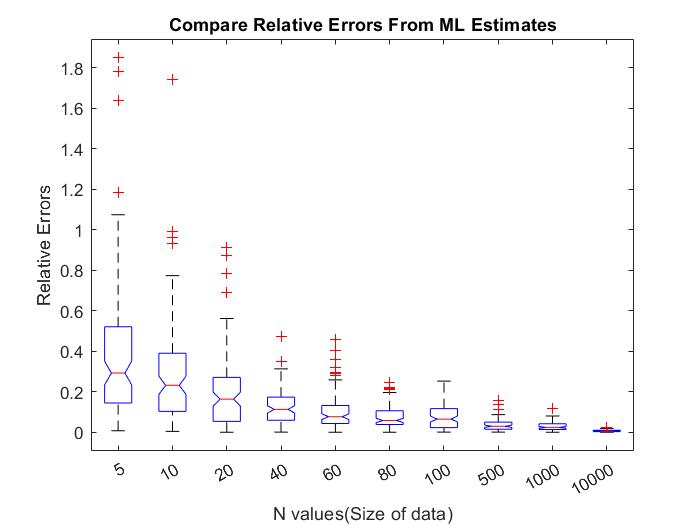

figure 
boxplot(errors_ML,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From ML Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

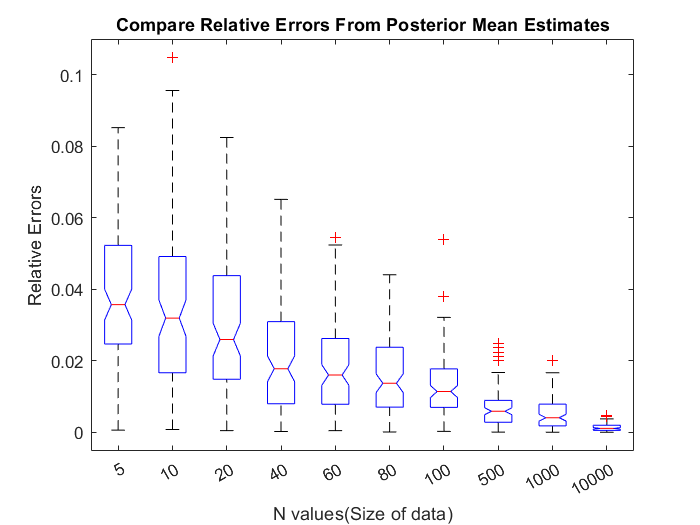

figure 
boxplot(errors_MAP1,'Notch','on','Labels',N)
title(sprintf('Compare Relative Errors From Posterior Mean Estimates'))
xlabel(sprintf('N values(Size of data)'))
ylabel('Relative Errors')

figure
boxplot(errors_ML, 'Colors',"b", 'Notch', 'on');
hold on;
boxplot(errors_posterior, 'Colors',"k",'Notch','on', 'Labels',N);
xlabel('N values (Size of Data)');
ylabel('Relative Errors');
title('Compare Relative Errors');
L(1) = plot(nan,nan,'-b');
L(2) = plot(nan,nan,'-k');
legend(L, {'ML', 'Posterior Mean'});

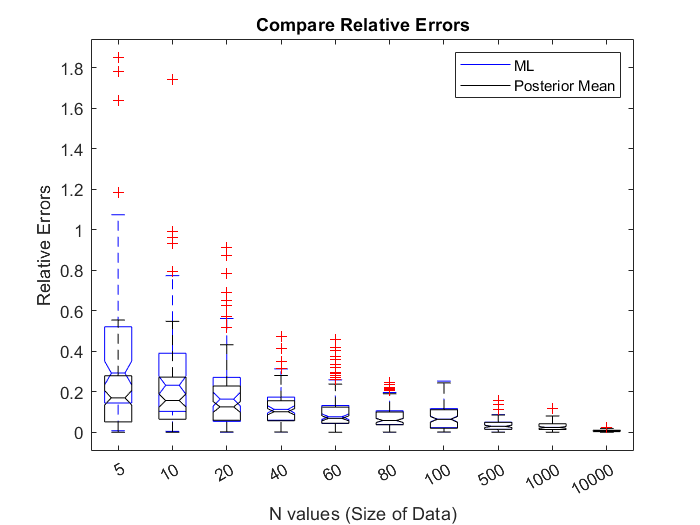

hold off;